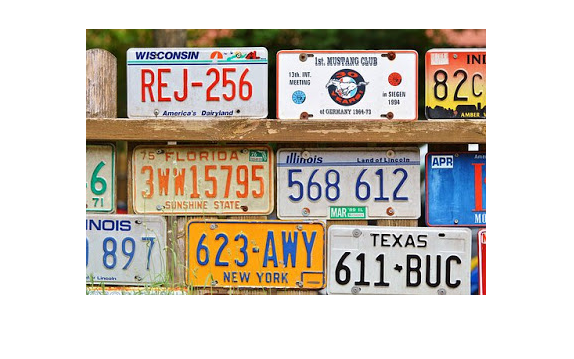

clear all;
img = imread("identifications.jpg");
figure, imshow(img);

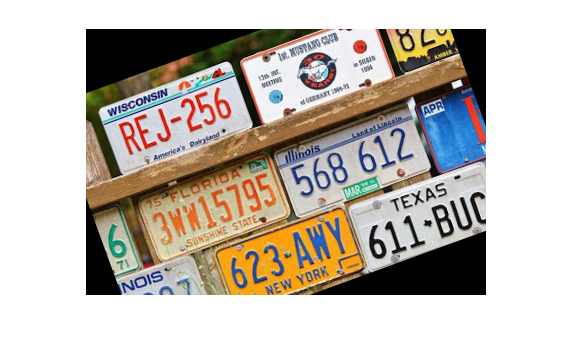

img_2 = imrotate(img,20,'bilinear','crop');
figure, imshow(img_2);

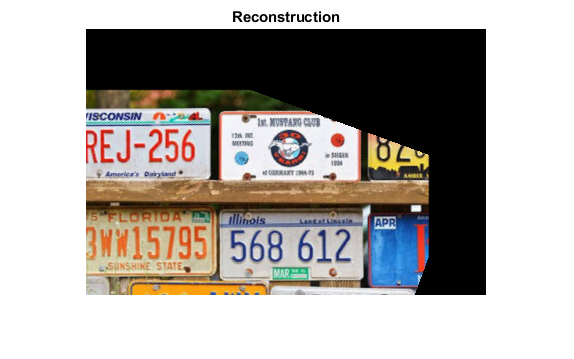


theta = -20;
tform = projective2d([cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1]);
Rin = imref2d( size(img_2) );   
Rin.XWorldLimits = [0 400];
Rin.YWorldLimits = [0 266];
outputImage = imwarp(img_2,tform,'OutputView', Rin);
%outputImage = imwarp(img_2,tform,'OutputView',imref2d(size(img_2)));
figure, imshow(outputImage);title("Reconstruction");

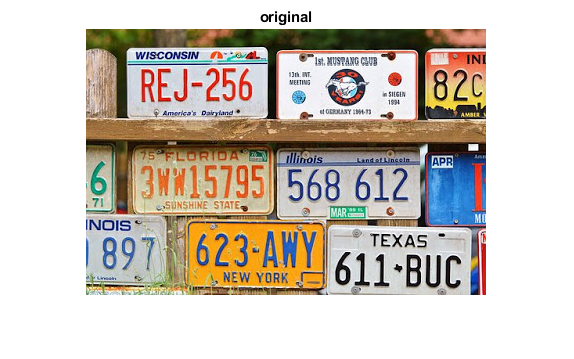

figure; imshow(img);title("original");

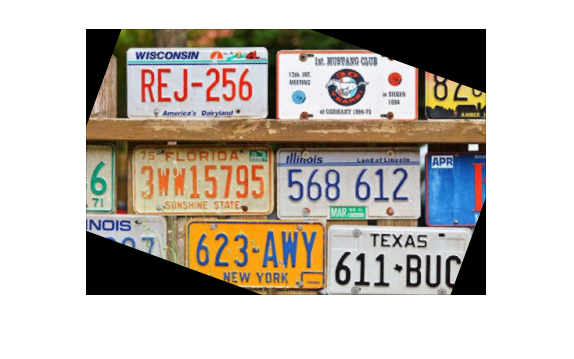

img_rec = imrotate(img_2,-20,'bilinear','crop');
figure, imshow(img_rec);

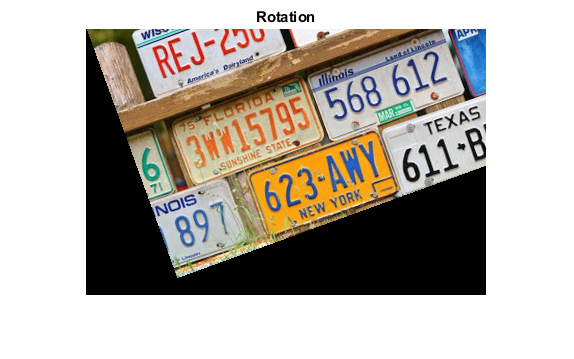

theta = 20;
tform = projective2d([cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1]);
Rin = imref2d( size(img) );   
%Rin.XWorldLimits = [0 400];
%Rin.YWorldLimits = [0 266];
out = imwarp(img,tform,'OutputView', Rin);
%outputImage = imwarp(img_2,tform,'OutputView',imref2d(size(img_2)));
figure, imshow(out);title("Rotation");

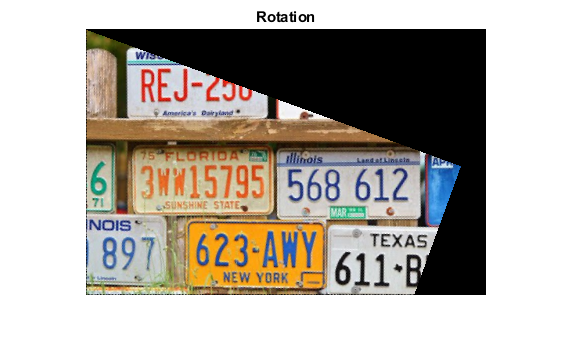

theta = -20;
tform = projective2d([cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1]);
Rin = imref2d( size(out) );   
%Rin.XWorldLimits = [0 400];
%Rin.YWorldLimits = [0 266];
outputImage = imwarp(out,tform,'OutputView', Rin);
%outputImage = imwarp(img_2,tform,'OutputView',imref2d(size(img_2)));
figure, imshow(outputImage);title("Rotation");